# Transfer Learning Using Vgg16

This example shows how to fine-tune a pretrained Vgg16 convolutional neural network to perform classification on a new collection of images.

Vgg16 has been trained on over a million images and can classify images into 1000 object categories (such as keyboard, coffee mug, pencil, and many animals). The network has learned rich feature representations for a wide range of images. The network takes an image as input and outputs a label for the object in the image together with the probabilities for each of the object categories.

Transfer learning is commonly used in deep learning applications. You can take a pretrained network and use it as a starting point to learn a new task. Fine-tuning a network with transfer learning is usually much faster and easier than training a network with randomly initialized weights from scratch. You can quickly transfer learned features to a new task using a smaller number of training images.

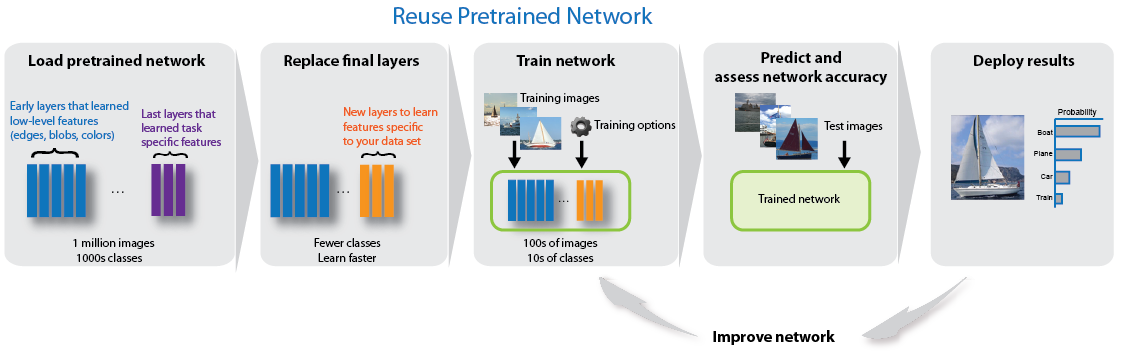

## Load Data

Unzip and load the new images as an image datastore. `imageDatastore` automatically labels the images based on folder names and stores the data as an `ImageDatastore` object. An image datastore enables you to store large image data, including data that does not fit in memory, and efficiently read batches of images during training of a convolutional neural network.

unzip('MerchData.zip');
imds = imageDatastore('MerchData', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

Divide the data into training and validation data sets. Use 70% of the images for training and 30% for validation. `splitEachLabel` splits the `images` datastore into two new datastores.

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

This very small data set now contains 55 training images and 20 validation images. Display some sample images.

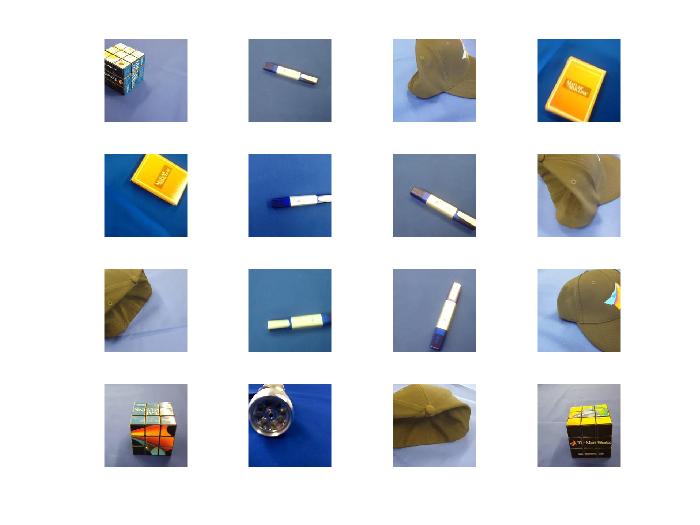

numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end

## Load Pretrained Network

Load the pretrained Vgg16 neural network. If Neural Network Toolbox™ Model *for Vgg16 Network* is not installed, then the software provides a download link. Vgg16 is trained on more than one million images and can classify images into 1000 object categories, such as keyboard, mouse, pencil, and many animals. As a result, the model has learned rich feature representations for a wide range of images.

net = vgg16;

Display the network architecture. The network has five convolutional layers and three fully connected layers.

net.Layers

ans =   41x1 Layer array with layers:

     1   'input'     Image Input             224x224x3 images with 'zerocenter' normalization
     2   'conv1_1'   Convolution             64 3x3x3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'relu1_1'   ReLU                    ReLU
     4   'conv1_2'   Convolution             64 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     5   'relu1_2'   ReLU                    ReLU
     6   'pool1'     Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'conv2_1'   Convolution             128 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     8   'relu2_1'   ReLU                    ReLU
     9   'conv2_2'   Convolution             128 3x3x128 convolutions with stride [1  1] and padding [1  1  1  1]
    10   'relu2_2'   ReLU                    ReLU
    11   'pool2'     Max Pooling   

The first layer, the image input layer, requires input images of size 227-by-227-by-3, where 3 is the number of color channels. 

inputSize = net.Layers(1).InputSize

inputSize =    224   224     3


## Replace Final Layers

The last three layers of the pretrained network `net` are configured for 1000 classes. These three layers must be fine-tuned for the new classification problem. Extract all layers, except the last three, from the pretrained network.

layersTransfer = net.Layers(1:end-3);

Transfer the layers to the new classification task by replacing the last three layers with a fully connected layer, a softmax layer, and a classification output layer. Specify the options of the new fully connected layer according to the new data. Set the fully connected layer to have the same size as the number of classes in the new data. To learn faster in the new layers than in the transferred layers, increase the `WeightLearnRateFactor` and `BiasLearnRateFactor` values of the fully connected layer.

numClasses = numel(categories(imdsTrain.Labels))

numClasses = 5

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

## Train Network

The network requires input images of size 227-by-227-by-3, but the images in the image datastores have different sizes. Use an augmented image datastore to automatically resize the training images. Specify additional augmentation operations to perform on the training images: randomly flip the training images along the vertical axis, and randomly translate them up to 30 pixels horizontally and vertically. Data augmentation helps prevent the network from overfitting and memorizing the exact details of the training images.  

pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

To automatically resize the validation images without performing further data augmentation, use an augmented image datastore without specifying any additional preprocessing operations.

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

Specify the training options. For transfer learning, keep the features from the early layers of the pretrained network (the transferred layer weights). To slow down learning in the transferred layers, set the initial learning rate to a small value. In the previous step, you increased the learning rate factors for the fully connected layer to speed up learning in the new final layers. This combination of learning rate settings results in fast learning only in the new layers and slower learning in the other layers. When performing transfer learning, you do not need to train for as many epochs. An epoch is a full training cycle on the entire training data set. Specify the mini-batch size and validation data. The software validates the network every `ValidationFrequency` iterations during training.

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',3, ...
    'ValidationPatience',Inf, ...
    'Verbose',false, ...
    'Plots','training-progress');

Train the network that consists of the transferred and new layers. By default, `trainNetwork` uses a GPU if one is available (requires Parallel Computing Toolbox™ and a CUDA® enabled GPU with compute capability 3.0 or higher). Otherwise, it uses a CPU. You can also specify the execution environment by using the `'ExecutionEnvironment'` name-value pair argument of `trainingOptions`.

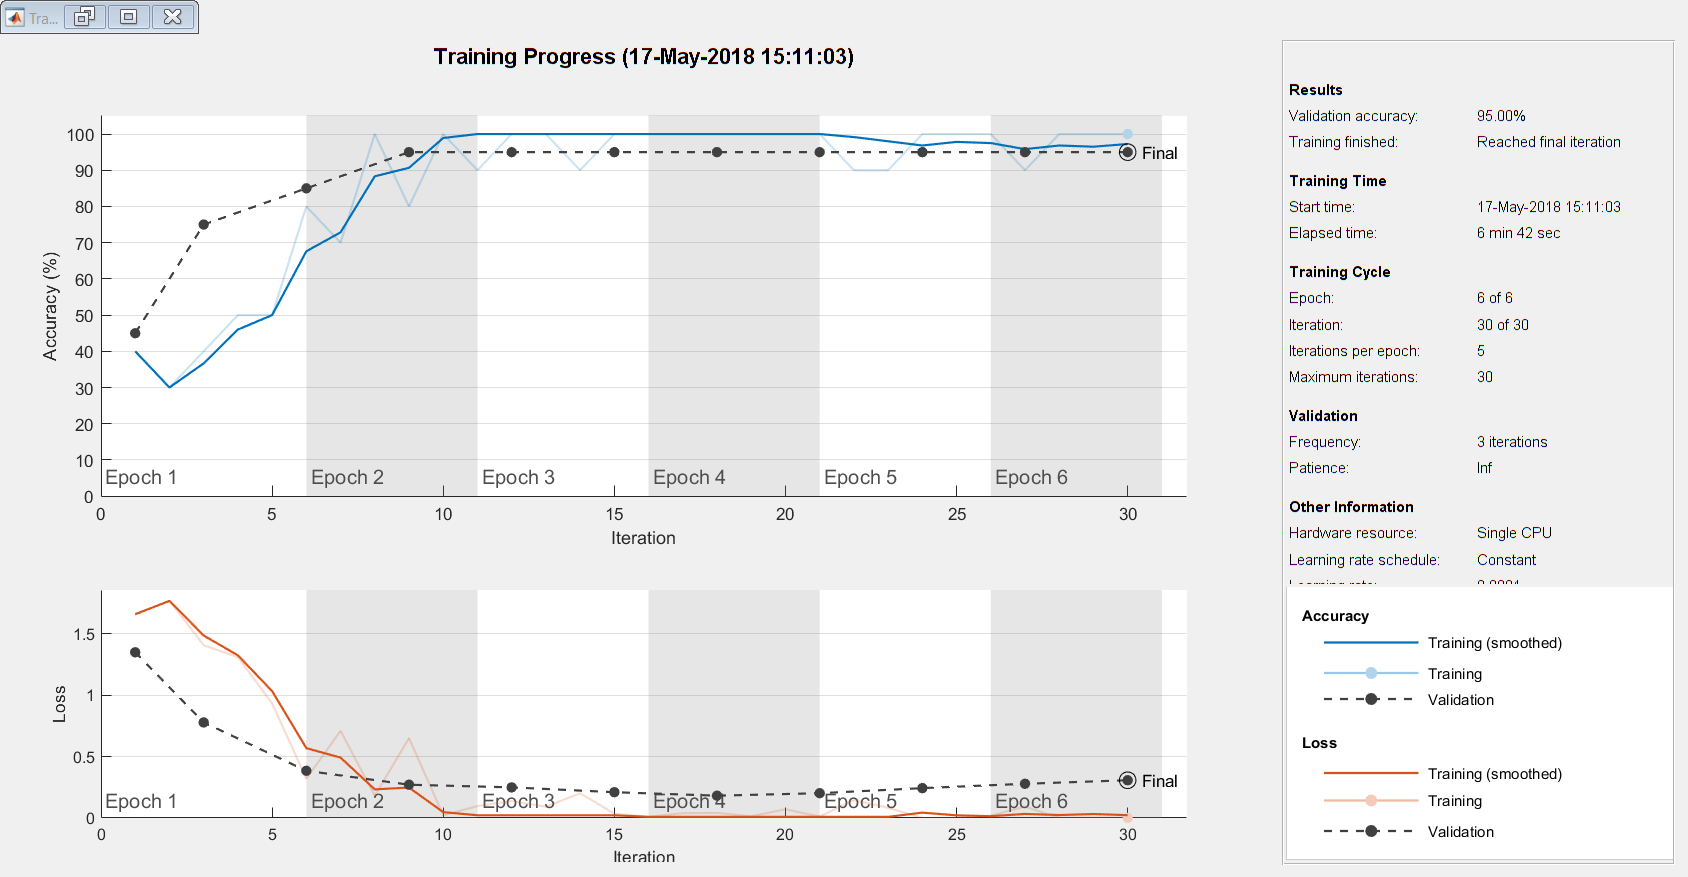

netTransfer = trainNetwork(augimdsTrain,layers,options);

## Classify Validation Images

Classify the validation images using the fine-tuned network.

[YPred,scores] = classify(netTransfer,augimdsValidation);

Display four sample validation images with their predicted labels.

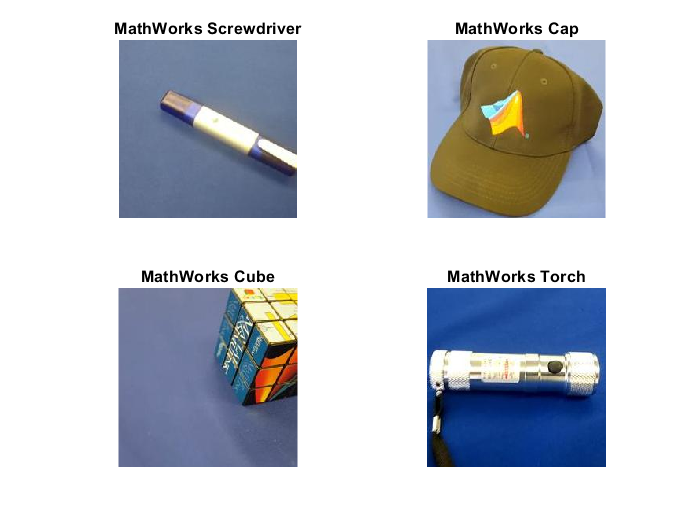

idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label));
end

Calculate the classification accuracy on the validation set. Accuracy is the fraction of labels that the network predicts correctly.

YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation)

accuracy = 0.9500

This trained network has high accuracy. If the accuracy is not high enough using transfer learning, then try feature extraction instead.